## **Assignment-I**

**Department of Applied Mathematics**

**Noakhali Science and Technology University**

**Course Code: A.MTH 4102, Course Title: Math Practical -V (Using MATLAB)**

*“First, solve the problem. Then, write the code.” *

***Programmer(Microsoft)– John Johnson***

**Question-1:**  Write a MATLAB code that will take any two numbers as input and will print their sum and product as output with suitable description.

**Answer:**

a = input("Enter 1st number ") %s)

a = 12

b = input("Enter 2nd number ") %s)

b = 12

fprintf("sum of %d and %d is %d", a, b, a+b)

sum of 12 and 12 is 24

fprintf("product of %d and %d is %d", a, b, a*b)

product of 12 and 12 is 144

**Question-2:** Use MATLAB code to determine volume and total surface area of right circular cone with  radius of base area 3cm and height 5cm.

**Answer: **

we know , volume of right circular cone is  $V=\pi \;r^{2\;} \frac{h}{3}\;\ldotp \;$and area is $A=\pi r\left(r+\sqrt{\;\left(h^{2\;} +r^2 \right)}\;\right)$

rb = 3

rb = 3

ht = 5

ht = 5

volume = pi*rb.^2 * ht./ 3

volume = 47.1239

sa = pi*rb*( rb+ sqrt(ht.^2 + rb.^2))

sa = 83.2298

fprintf("volume is %d \nsurface area is %d", volume, sa)

volume is 4.712389e+01 
surface area is 8.322976e+01

**Question-3:** Use MATLAB code to draw graphs for y = sin2x and its derivative in a single figure with  suitable distinction and legend. Regard that 𝑥 varies from 0 to 2𝜋.

**Answer: **

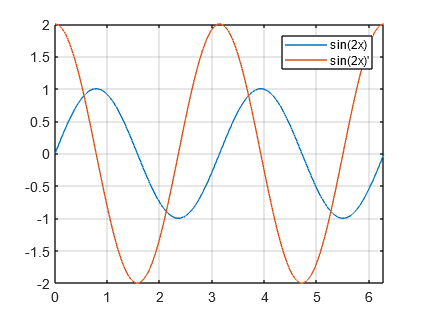

x = 0:0.01:2*pi;
hold off
plot(x,sin(2*x)), grid on
hold on;
plot(x,2*cos(2*x))
legend("sin(2x)", "sin(2x)'")
hold off

**Question-4:** Using MATLAB code, print the coordinates of 11 points in a tabular form of the polynomial  function $y=-3\;x^5 +10\;x^3 -5x+1,-5\le x\le 5$. Also, draw graphs for the same  polynomial function using both (a) 11 points and (b) 101 points along with comments.

**Answer:**

x = linspace(-5,5,11);
x1 = linspace(-5,5,101);
y = fun1(x);
fprintf('%11s %18s\n','x','y')

          x                  y


for n = 1:length(x)
    fprintf('%14s %20s\n',x(n),y(n))
end

 -5.000000e+00                    ῗ
 -4.000000e+00                    ক
 -3.000000e+00                    Ǜ
 -2.000000e+00                    
 -1.000000e+00        -1.000000e+00
                                  
                                 
                     -2.500000e+01
                     -4.730000e+02
                     -2.451000e+03
                     -8.149000e+03


hold off

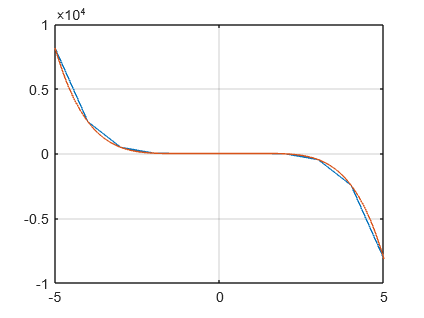

plot(x,fun1(x)), grid on
hold on;

plot(x1,fun1(x1))
hold off

**Question 5:** Using MATLAB code, plot the graphs of the following functions/equations using different  colors, marker style and/or line style:  (a) 𝑦 = |𝑥|, −10 ≤ 𝑥 ≤ 10 (b) 𝑦 = 𝑥 2 − 10𝑥 + 15, 𝑥 varies from 0 to 10 .

**Answer:**

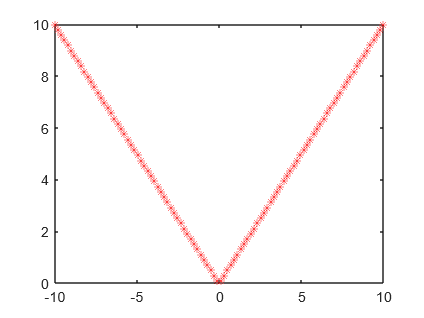

x = linspace(-10,10,100);
p1 = plot(x,abs(x),"*r");

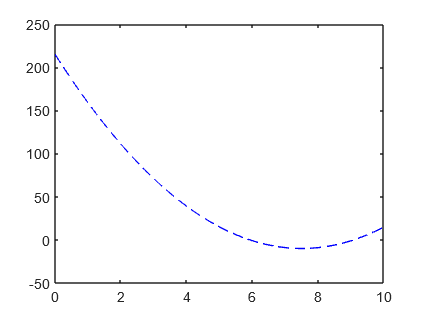

x1 = linspace(0,10,100);
p2 = plot(x1, x.^2-10*x+15, '--b');

**Question 6:** Write MATLAB code that reads an input temperature in degrees, farenheit, converts it to absolute temperature in kelvns and writes out the result. also, convert the following to tempareture in kelvins: (a) $-{50}^{o\;} \;\textrm{Farenheit}$ (b) ${170}^{o\;} \textrm{Farenheit}$.

n= input("how manay to convert:");
for i = 1:n
 F(i) = input("Enter the value in farenheit =");
end
size(F)

ans =      1     2


K = (((F-32)*5)./9) + 273.5;
fprintf('%4s %12s\n','Farenheit','Kelvin');

Farenheit       Kelvin


for i=1:n
    fprintf('%4d %17.2f\n',F(1,i),K(1,i));
end

 -50            227.94
 170            350.17


**Question 7:** Write a MATLAB code that will take coefficients 𝑎, 𝑏 and 𝑐 of the quadratic equation 𝑎𝑥 2 + 𝑏𝑥 + 𝑐 = 0 and will solve for the roots, whether they are distinct real roots, repeated real roots  or complex roots. Also, use this program to find the roots of the following equations along with  verification for at least one root of each: 


$$\left(a\right)\;4{\textrm{𝑥}}^2 -12\textrm{𝑥}+9=0$$



$$\left(b\right)2{\textrm{𝑥}}^2 -3\textrm{𝑥}-4=0$$



$$\left(c\right)7{\textrm{𝑥}}^2 -4\textrm{𝑥}+10=0$$


**Answer:**

quadraticEquation(4,-12,9)

The equation has only identical real roots
    1.5000



quadraticEquation(2,-3,-4)

The equation has two real roots
    2.3508

   -0.8508



quadraticEquation(7,-4,10)

Determinant < 0 The equation does not have a real root
complex roots are
14.000000-56.868269j
14.000000+56.868269j


**Question-8:** Write a program that reads the percentage of carbon 14 remaining in a sample, calculates the  age of the sample from it and prints out the result with proper units. 

**Answer:**

A =  input("enter remaining percent of carbon");
tHalf = 5600;
decayRate = -0.693/tHalf;
t = log(A/100)/(decayRate);
fprintf("age of sample is %0.4fyears",t)

age of sample is 15330.2625years

**Question-9: ** Use MATLAB code that reads coordinates of the three vertices of a triangle and prints out its  area.

**Answer:**

vert = NaN(3,2);
for i=1:3
    p = input("enter vertices");
    vert(i,1)=p(1);
    vert(i,2)=p(2);
end
vert(4,:)= vert(1,:);
area= 0;
for i=1:3
    area = area + vert(i,1)*vert(i+1,2) - vert(i,2)*vert(i+1,1);
end
area= 0.5*abs(area);
fprintf("Area of triangle is %.2f",area);

Area of triangle is 11.00

**Question 10: ** Write a MATLAB program to evaluate a function 𝑓(𝑥, 𝑦) for any two user-specified values of  𝑥 and 𝑦. The function 𝑓(𝑥, 𝑦) is defined as follows.


$$f\left(x,y\right)=\left\lbrack \begin{array}{cc}
x+y & x\ge 0\;\textrm{and}\;y\ge 0\\
x+y^2  & x\ge 0\;\textrm{and}\;y<0\\
x^2 +y & x<0\;\textrm{and}\;y\ge 0\\
x^2 +y^2  & x<0\;\textrm{and}\;y<0
\end{array}\right\rbrack$$


syms y(x,y) x y
y(x,y) = piecewise((x>=0)&(y>=0),x+y,(x>=0)&(y<0),x+y^2,(x<0)&(y>=0),x^2 + y,(x<0)&(y<0),x^2 + y^2);
%===========solution(a)==============%
disp(y(2,3))

$$5$$

%===========solution(b)==============%
disp(y(2,-3))

$$11$$

%===========solution(c)==============%
disp(y(-2,3))

$$7$$

%===========solution(d)==============%
disp(y(-2,-3))

$$13$$

function y = quadraticEquation(a,b,c)

    delta = (b.^2)-(4*a*c);
    if(delta < 0)
        disp("Determinant < 0 The equation does not have a real root");
        x1 = (-b - sqrt(delta))/2*a;
        x2 = (-b + sqrt(delta))/2*a;
        fprintf("complex roots are\n")
        fprintf('%f%+fj\n', real(x1), imag(x1))
        fprintf('%f%+fj\n', real(x2), imag(x2))
    elseif (delta == 0)
        disp('The equation has only identical real roots');
        disp(-b./(2*a));
    else
        disp('The equation has two real roots');
        disp((-b+sqrt(delta))./(2*a));
        disp((-b-sqrt(delta))./(2*a));
    
    end
end


function y = fun1(x)
    y = -3*x.^5 + 10*x.^3 - 5*x +1;
end
